close all
clear

data = load("../data/hourly_data.dat");
s = size(data);
n_stations = s(2) - 1;
station_array = (1:n_stations).';

x = data(3:end, 1);
y = data(3:end, 2:end).';

figure
h = pcolor(x, station_array, y);colorbar
set(h, 'EdgeColor', 'none');
datetick('x')
title("Full Hourly Dataset")
xlabel("Time")
ylabel("Station #")

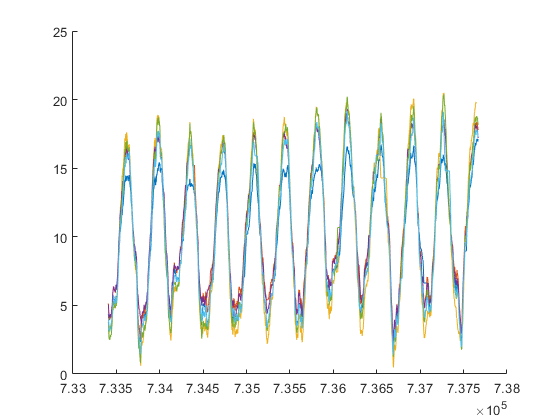

figure
hold on
for i = 10:15
    temp_y = y(i, :);
    mask = ~isnan(temp_y);
    temp_y = temp_y(mask);
    temp_x = x(mask);
    plot(temp_x, movmean(temp_y, 1000))
end  
hold off

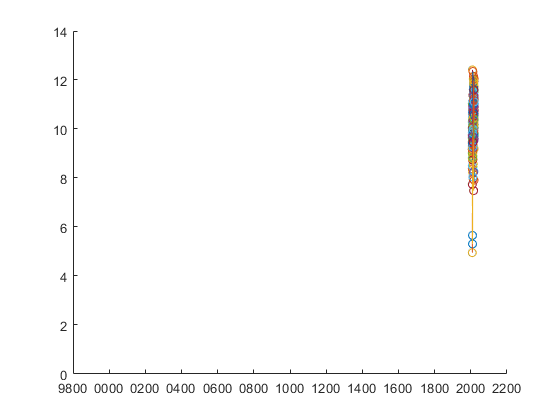

lon =  data(1:1, 2:end);
lat =  data(2:2, 2:end);
hold on
for i = 1:length(lon)
    year_mean = [];
    year_middle = [];
    for iYear = 2008:2018
        t_start = datenum(iYear,1,1,0,0,0);
        t_end   = datenum(iYear,12,31,23,59,59);
        [times, temps] = getdata(data, lon(i), lat(i), t_start, t_end);
        m = nanmean(temps);
        year_mean = [year_mean m];
        year_middle= [year_middle (t_end+t_start)/2];
    end 
    hold on
    plot(year_middle, year_mean);
    datetick('x')
end

lon =  data(1:1, 2:end);
lat =  data(2:2, 2:end);
i = 1;
figure()
hold on
for iYear = 2008:2010
    disp(iYear)
    disp(iYear-2007)
    t_start = datenum(iYear,1,1,0,0,0);
    t_end   = datenum(iYear,12,31,23,59,59);
    [times, temps] = getdata(data, lon(i), lat(i), t_start, t_end);
    m = nanmean(temps);
    year_mean(iYear-2007) = m;
    year_middle(iYear-2007) = (t_end+t_start)/2;
    disp((t_end-t_start)/2)
    scatter(t_start, m)
    datetick('x')
end
datetick('x')